[a,d] = haart(ab_diff_train_norm, 10)

a =    11.7433
   16.2949
   11.0417
   11.9143
   10.8380
   12.1646
   12.7020
   11.7554
   12.3481
   10.7796
   11.4627
   11.1372
   15.1956
   11.3160
   13.8600


d = 1×10 cell array
    {26399×1 double}    {13199×1 double}    {6600×1 double}    {3300×1 double}    {1650×1 double}    {825×1 double}    {412×1 double}    {206×1 double}    {103×1 double}    {52×1 double}


Haar_4 = ihaart(a,d,2)

Haar_4 =     0.0866
    0.0866
    0.0866
    0.0866
    0.4830
    0.4830
    0.4830
    0.4830
    0.0441
    0.0441
    0.0441
    0.0441
    0.0441
    0.0441
    0.0441


Haar_5 = ihaart(a,d,5)

Haar_5 =     0.1718
    0.1718
    0.1718
    0.1718
    0.1718
    0.1718
    0.1718
    0.1718
    0.1718
    0.1718
    0.1718
    0.1718
    0.1718
    0.1718
    0.1718


Haar_7 = ihaart(a,d,7)

Haar_7 =     0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621


Haar_9 = ihaart(a,d,9)

Haar_9 =     0.3433
    0.3433
    0.3433
    0.3433
    0.3433
    0.3433
    0.3433
    0.3433
    0.3433
    0.3433
    0.3433
    0.3433
    0.3433
    0.3433
    0.3433



HaarResults = {Haar_4, Haar_5, Haar_7, Haar_9};


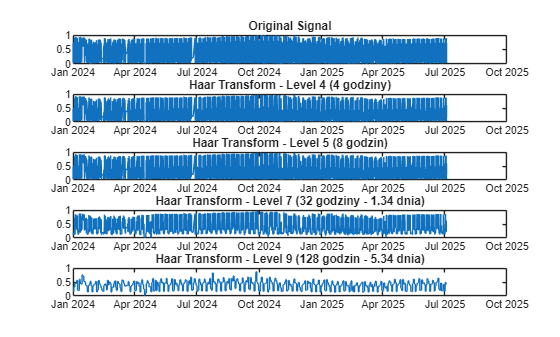

 
% Create a 4x1 subplot layout
subplot(5, 1, 1);
plot(ab_diff_train.Time, ab_diff_train_norm);
title('Original Signal');

subplot(5, 1, 2); % Specify the second subplot
plot(ab_diff_train.Time, HaarResults{1}); % Plot Haar_4
title('Haar Transform - Level 4 (4 godziny)');

subplot(5, 1, 3); % Specify the second subplot
plot(ab_diff_train.Time, HaarResults{1}); % Plot Haar_5
title('Haar Transform - Level 5 (8 godzin)');

subplot(5, 1, 4); % Specify the third subplot
plot(ab_diff_train.Time, HaarResults{2}); % Plot Haar_7
title('Haar Transform - Level 7 (32 godziny - 1.34 dnia)');

subplot(5, 1, 5); % Specify the fourth subplot
plot(ab_diff_train.Time, HaarResults{3}); % Plot Haar_9
title('Haar Transform - Level 9 (128 godzin - 5.34 dnia)');

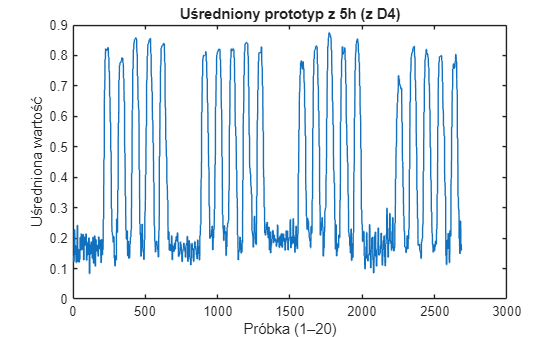

% --- Prototyp 5h z poziomu D4---
P_5h = 96*7*4;

signal_5h = Haar_4;
num_periods_5h = floor(length(signal_5h) / P_5h);
signal_5h_trimmed = signal_5h(1 : num_periods_5h * P_5h);

matrix_5h = reshape(signal_5h_trimmed, P_5h, num_periods_5h);
prototyp_5h = mean(matrix_5h, 2);

figure;
plot(prototyp_5h);
title('Uśredniony prototyp z 5h (z D4)');
xlabel('Próbka (1–20)');
ylabel('Uśredniona wartość');

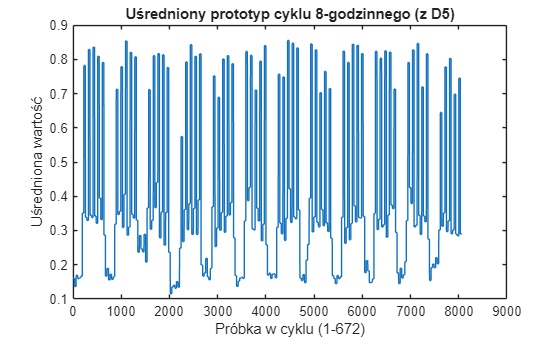

% --- Prototyp 8h z poziomu D5---
P_8h = 96 * 7* 4 * 3;
signal_8h = Haar_5;

% 2. Przytnij sygnał, aby był wielokrotnością okresu
num_periods_8h = floor(length(signal_8h) / P_8h);
signal_8h_trimmed = signal_8h(1 : num_periods_8h * P_8h);

% 3. Przekształć na macierz (każda kolumna to jeden cykl)
matrix_8h = reshape(signal_8h_trimmed, P_8h, num_periods_8h);

% 4. Oblicz średni cykl (uśrednij wzdłuż wierszy)
prototyp_8h = mean(matrix_8h, 2);

% 5. Wizualizacja
figure;
plot(prototyp_8h);
title('Uśredniony prototyp cyklu 8-godzinnego (z D5)');
xlabel('Próbka w cyklu (1-672)');
ylabel('Uśredniona wartość');

% --- Prototyp 24h z poziomu D7---
P_24h = 96*7*4;
signal_24h = Haar_7

signal_24h =     0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621


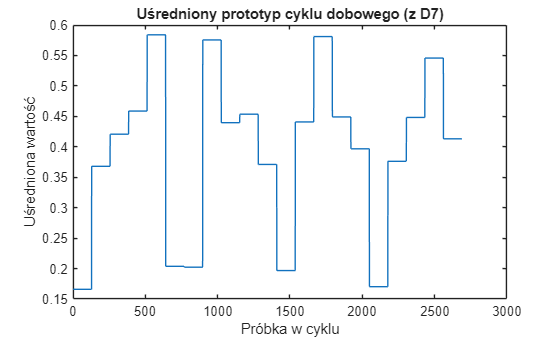


% 2. Przytnij sygnał
num_periods_24h = floor(length(signal_24h) / P_24h);
signal_24h_trimmed = signal_24h(1 : num_periods_24h * P_24h);

% 3. Przekształć na macierz
matrix_24h = reshape(signal_24h_trimmed, P_24h, num_periods_24h);

% 4. Oblicz średni cykl
prototyp_24h = mean(matrix_24h, 2);

% 5. Wizualizacja
figure;
plot(prototyp_24h);
title('Uśredniony prototyp cyklu dobowego (z D7)');
xlabel('Próbka w cyklu');
ylabel('Uśredniona wartość');

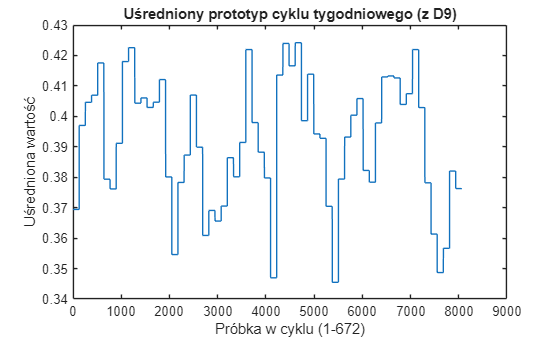

% --- Prototyp 7 dni z poziomu D9---
P_tydzien = 96 * 7 * 4 * 3;
signal_tydzien = Haar_9;

% 2. Przytnij sygnał
num_periods_tydzien = floor(length(signal_tydzien) / P_tydzien);
signal_tydzien_trimmed = signal_tydzien(1 : num_periods_tydzien * P_tydzien);

% 3. Przekształć na macierz
matrix_tydzien = reshape(signal_tydzien_trimmed, P_tydzien, num_periods_tydzien);

% 4. Oblicz średni cykl
prototyp_tydzien = mean(matrix_tydzien, 2);

% 5. Wizualizacja
figure;
plot(prototyp_tydzien);
title('Uśredniony prototyp cyklu tygodniowego (z D9)');
xlabel('Próbka w cyklu (1-672)');
ylabel('Uśredniona wartość');

dlugosc_calosci = length(ab_diff_train.Var1) + length(ab_diff_test.Var1);
dlugosc_treningu = length(ab_diff_train.Var1);
dlugosc_testu = length(ab_diff_test.Var1);

% Zbuduj model 4h
model_5h = zeros(dlugosc_calosci, 1);
for i = 1:dlugosc_calosci
    model_5h(i) = funkcja_sezonowa(i, prototyp_5h * 1);
end
model_5h_centered = model_5h - mean(model_5h);

rmse_5h = rmse(model_5h(1:dlugosc_treningu,:), Haar_4)

rmse_5h = 0.1759

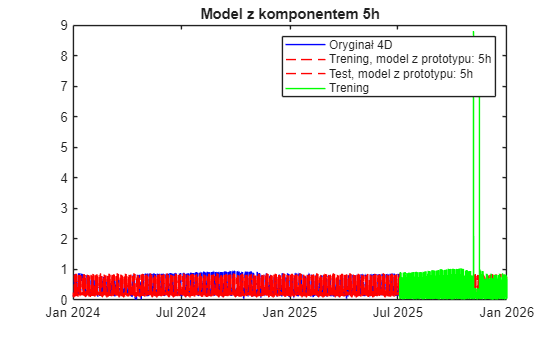


% Wizualizacja
figure;
plot(ab_diff_train.Time, Haar_5, 'b', 'DisplayName', 'Oryginał 4D');
hold on;
plot(ab_diff_train.Time, model_5h(1:dlugosc_treningu,:), 'r--', 'DisplayName', 'Trening, model z prototypu: 5h');
plot(ab_diff_test.Time, model_5h(dlugosc_treningu+1:end,:), 'r--', 'DisplayName', 'Test, model z prototypu: 5h');
plot(ab_diff_test.Time, ab_diff_test_norm, 'g', 'DisplayName', 'Trening');

legend;
title('Model z komponentem 5h');

% Zbuduj model 8h
model_8h = zeros(dlugosc_calosci, 1);
for i = 1:dlugosc_calosci
    model_8h(i) = funkcja_sezonowa(i, prototyp_8h);
end
model_8h_centered = model_8h - mean(model_8h);

rmse_8h = rmse(model_8h(1:dlugosc_treningu,:), Haar_5)

rmse_8h = 0.1102

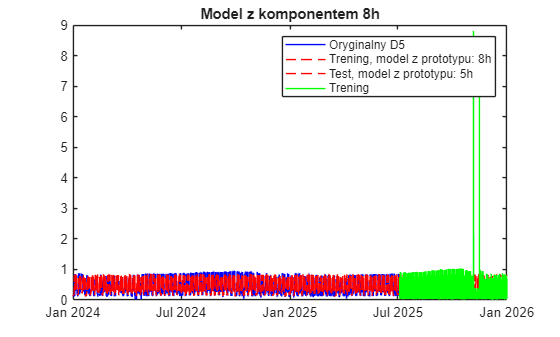


% Wizualizacja
figure;
plot(ab_diff_train.Time, Haar_5, 'b', 'DisplayName', 'Oryginalny D5');
hold on;
plot(ab_diff_train.Time, model_8h(1:dlugosc_treningu,:), 'r--', 'DisplayName', 'Trening, model z prototypu: 8h');
plot(ab_diff_test.Time, model_8h(dlugosc_treningu+1:end,:), 'r--', 'DisplayName', 'Test, model z prototypu: 5h');
plot(ab_diff_test.Time, ab_diff_test_norm, 'g', 'DisplayName', 'Trening');


legend;
title('Model z komponentem 8h');

% Zbuduj model 24h
model_24h = zeros(dlugosc_calosci, 1);
for i = 1:dlugosc_calosci
    model_24h(i) = funkcja_sezonowa(i, prototyp_24h);
end
model_24h_centered = model_24h - mean(model_24h);

rmse_24h = rmse(model_24h(1:dlugosc_treningu,:), Haar_7)

rmse_24h = 0.0802

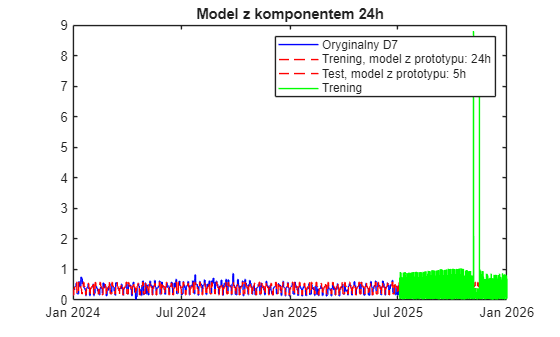


% Porównaj zrekonstruowany model z sygnałem D7
figure;
plot(ab_diff_train.Time, Haar_7, 'b', 'DisplayName', 'Oryginalny D7');
hold on;
plot(ab_diff_train.Time, model_24h(1:dlugosc_treningu,:), 'r--', 'DisplayName', 'Trening, model z prototypu: 24h');
plot(ab_diff_test.Time, model_24h(dlugosc_treningu+1:end,:), 'r--', 'DisplayName', 'Test, model z prototypu: 5h');
plot(ab_diff_test.Time, ab_diff_test_norm, 'g', 'DisplayName', 'Trening');


legend;
title('Model z komponentem 24h');

% Zbuduj model 7 dni
model_7d = zeros(dlugosc_calosci, 1);
for i = 1:dlugosc_calosci
    model_7d(i) = funkcja_sezonowa(i, prototyp_tydzien);
end
model_7d_centered = model_7d - mean(model_7d);

rmse_7d = rmse(model_7d(1:dlugosc_treningu,:), Haar_7)

rmse_7d = 0.1441

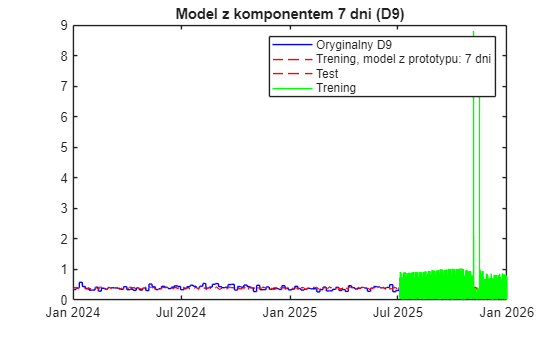


% Porównaj zrekonstruowany model z sygnałem D9
figure;
plot(ab_diff_train.Time, Haar_9, 'b', 'DisplayName', 'Oryginalny D9');
hold on;
plot(ab_diff_train.Time, model_7d(1:dlugosc_treningu,:), 'r--', 'DisplayName', 'Trening, model z prototypu: 7 dni');
plot(ab_diff_test.Time, model_7d(dlugosc_treningu+1:end,:), 'r--', 'DisplayName', 'Test');
plot(ab_diff_test.Time, ab_diff_test_norm, 'g', 'DisplayName', 'Trening');
legend;
title('Model z komponentem 7 dni (D9)');

trend_MA_original = movmean(ab_diff_train_norm,672*4)

trend_MA_original =     0.3957
    0.3959
    0.3962
    0.3964
    0.3967
    0.3969
    0.3971
    0.3974
    0.3976
    0.3979
    0.3981
    0.3983
    0.3986
    0.3988
    0.3991



sum_of_4_signals =  model_5h_centered(1:dlugosc_treningu,:)  + model_24h_centered(1:dlugosc_treningu,:) + model_7d_centered(1:dlugosc_treningu,:) + trend_MA_original

sum_of_4_signals =    -0.1078
   -0.1076
   -0.1073
   -0.1071
   -0.1227
   -0.1225
   -0.1222
   -0.1220
   -0.0169
   -0.0166
   -0.0164
   -0.0161
   -0.0973
   -0.0970
   -0.0968


rmse_sum_of_4_signals = rmse(sum_of_4_signals, ab_diff_train_norm)

rmse_sum_of_4_signals = 0.2425


trend_MA_original_test = movmean(ab_diff_test_norm,672*4)

trend_MA_original_test =     0.3764
    0.3762
    0.3760
    0.3758
    0.3756
    0.3754
    0.3752
    0.3750
    0.3748
    0.3745
    0.3743
    0.3740
    0.3740
    0.3739
    0.3738


sum_of_4_signals_test = model_5h_centered(dlugosc_treningu+1:end,:)  + model_24h_centered(dlugosc_treningu+1:end,:) + model_7d_centered(dlugosc_treningu+1:end,:) + trend_MA_original_test

sum_of_4_signals_test =     0.4411
    0.4408
    0.3438
    0.3436
    0.3434
    0.3432
    0.3697
    0.3695
    0.3693
    0.3690
    0.4210
    0.4208
    0.4207
    0.4206
    0.4916



mae_sum_of_4_signals_test = mae(sum_of_4_signals_test, ab_diff_test_norm)

mae_sum_of_4_signals_test = 0.2223

mape_sum_of_4_signals_test = mape(sum_of_4_signals_test, ab_diff_test_norm)

mape_sum_of_4_signals_test = 184.8204

rmse_sum_of_4_signals_test = rmse(sum_of_4_signals_test, ab_diff_test_norm)

rmse_sum_of_4_signals_test = 0.4713

r2_sum_of_4_signals_test = rmse(sum_of_4_signals_test, ab_diff_test_norm)

r2_sum_of_4_signals_test = 0.4713

r_squared_of_4_signals_test = calculate_r_squared(sum_of_4_signals_test, ab_diff_test_norm)

r_squared_of_4_signals_test = 0.2107

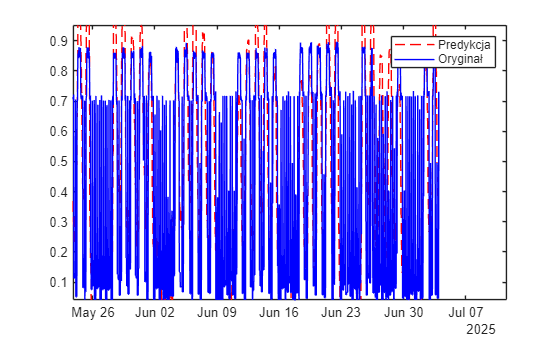


% Porównaj zrekonstruowany model
figure;
plot(ab_diff_train.Time, sum_of_4_signals, 'r--', 'DisplayName', 'Predykcja');
hold on;
plot(ab_diff_train.Time, ab_diff_train_norm, 'b', 'DisplayName', 'Oryginał');
legend;